## AOMIC PIOP2 Replication Sample - Whole-Brain Coupling Plot Across Conditions 

Computation of coupling measure-specific brain-average coupling values for all four conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. 

Before running this script: 

- run all scripts in AOMIC Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_rest{i,1} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_rest{i,2} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_rest{i,3} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_rest{i,4} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_rest_table = cell2table(whole_brain_values_AOMIC_PIOP2_rest);
 whole_brain_values_AOMIC_PIOP2_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_rest_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24049    0.24388    0.26184    0.19397
    0.18809    0.22514    0.23472    0.21443
    0.21149    0.24024      0.251    0.20192
    0.21095    0.21691    0.22397    0.17247
     0.2385    0.25695    0.27696    0.21922
    0.21308    0.22182    0.23073    0.17766
    0.25433    0.24283    0.26575    0.26113
    0.27584    0.27236    0.29538    0.25944
    0.20416    0.22716    0.23169    0.15163
    0.19635    0.21057    0.22009     0.1836
    0.20628    0.22505    0.23199    0.16663
    0.23088    0.26004    0.27557    0.18947
    0.23046    0.23447    0.25006    0.17273
    0.21638    0.23147     0.2546    0.19285
    0.23176    0.23781    0.24136    0.18421
    0.16612    0.19345    0.19014    0.113

1.2. Working memory

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_wm{i,1} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_wm{i,2} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_wm{i,3} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_wm{i,4} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_wm_table = cell2table(whole_brain_values_AOMIC_PIOP2_wm);
 whole_brain_values_AOMIC_PIOP2_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_wm_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24487    0.25883    0.26746    0.20754
    0.20289    0.24695    0.24787    0.20244
    0.21069    0.24733    0.25332    0.20007
    0.21424    0.23253    0.23675    0.15435
    0.22361    0.25041    0.25786      0.188
    0.22835    0.21778    0.22628    0.20149
    0.25382    0.25378    0.26666    0.24254
     0.2855    0.27659    0.29555    0.25475
    0.24239    0.25911    0.27211    0.21289
    0.21917     0.2406    0.24186    0.19293
    0.23035    0.23128    0.23804    0.21447
    0.22952    0.25895    0.26559    0.18341
    0.23628    0.25441    0.25767    0.17029
    0.23643    0.25431    0.27166    0.24829
    0.25089    0.25716    0.26373    0.18775
    0.20144     0.2348    0.23172    0.15087

1.3. Emotion matching 

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_emo_match{i,1} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_emo_match{i,2} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_emo_match{i,3} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_emo_match{i,4} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_emo_match_table = cell2table(whole_brain_values_AOMIC_PIOP2_emo_match);
 whole_brain_values_AOMIC_PIOP2_emo_match_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_emo_match_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24839    0.25688    0.26917    0.20926
    0.21916    0.25141    0.25101    0.20787
     0.2037    0.24052    0.24234    0.20255
    0.20582    0.22969    0.22882     0.1554
    0.22446     0.2496    0.25877     0.2037
    0.22392    0.21825    0.22369    0.20395
    0.23011    0.23754    0.24567    0.21954
    0.25904     0.2689     0.2844    0.21836
    0.21277    0.24294    0.25564    0.19955
    0.19952    0.21853     0.2177    0.18414
    0.24986    0.25416    0.26617    0.24267
    0.22169    0.24484    0.24772    0.16722
    0.20388    0.23667    0.23764    0.13483
    0.24626     0.2645    0.28662     0.2664
    0.22323     0.2397    0.24388    0.15812
    0.17765    0.21524    0.20988    

1.4. Stop signal

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,1} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,2} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,3} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,4} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_stop_signal_table = cell2table(whole_brain_values_AOMIC_PIOP2_stop_signal);
 whole_brain_values_AOMIC_PIOP2_stop_signal_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_stop_signal_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.29216    0.28801    0.29839    0.24369
    0.24776    0.28037    0.29027    0.27834
    0.26376    0.29398     0.3047    0.23845
    0.25162    0.26075    0.26857    0.19821
    0.23115    0.26916    0.26757    0.18292
    0.26114    0.24522    0.25229    0.24646
    0.25362    0.25167    0.26427     0.2517
     0.3194    0.30623    0.32813    0.29935
    0.25292    0.28132    0.29241    0.22617
    0.25564    0.26771    0.27234    0.25063
    0.26402    0.27503    0.28065    0.22592
    0.27196    0.28513    0.29015    0.21909
    0.27259    0.29506    0.30961    0.19155
    0.29756    0.30637     0.3344    0.33349
     0.2578    0.26617    0.27451     0.1963
    0.24998    0.27134    0.27814  

**2. Average coupling measures within the conditions **

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_rest_table.Pl whole_brain_values_AOMIC_PIOP2_rest_table.G whole_brain_values_AOMIC_PIOP2_rest_table.Cos whole_brain_values_AOMIC_PIOP2_rest_table.SI]
Rest_all = mean(Rest_values_from_all_measures,2)

2.2. Take average across all working memory values

Wm_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_wm_table.Pl whole_brain_values_AOMIC_PIOP2_wm_table.G whole_brain_values_AOMIC_PIOP2_wm_table.Cos whole_brain_values_AOMIC_PIOP2_wm_table.SI]
Wm_all = mean(Wm_values_from_all_measures,2)

2.3. Take average across all emotion matching values 

Emo_match_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_emo_match_table.Pl whole_brain_values_AOMIC_PIOP2_emo_match_table.G whole_brain_values_AOMIC_PIOP2_emo_match_table.Cos whole_brain_values_AOMIC_PIOP2_emo_match_table.SI]
Emo_match_all = mean(Emo_match_values_from_all_measures,2)

2.4. Take average across all stop signal values 

Stop_signal_from_all_measures = [whole_brain_values_AOMIC_PIOP2_stop_signal_table.Pl  whole_brain_values_AOMIC_PIOP2_stop_signal_table.G  whole_brain_values_AOMIC_PIOP2_stop_signal_table.Cos  whole_brain_values_AOMIC_PIOP2_stop_signal_table.SI]
Stop_signal_all = mean(Stop_signal_from_all_measures,2)

**3. Create the violin plot**

3.1. Put all values into one table

Mean_values_conditions = [Rest_all Wm_all Emo_match_all Stop_signal_all]

3.2. Create violin plots

violinplot(Mean_values_conditions)
ylabel('Brain-average Coupling (r)')
xlabel('Condition')
set(gca,'FontSize',15)
ylim([0.05 0.4])

**4. Run ANOVAs **

Mean_values_conditions
groupnames = {'rest','wm','emo-m','sto'}

groupnames = 1×4 cell array
    {'rest'}    {'wm'}    {'emo-m'}    {'sto'}


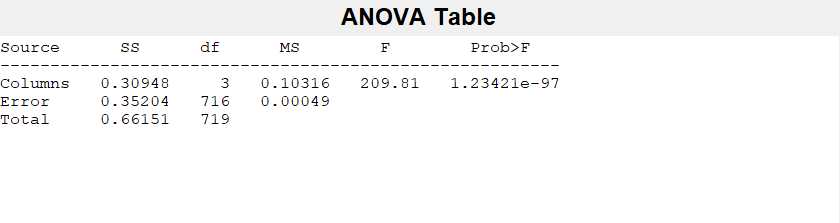

p = 1.2342e-97

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.3095]}    {[  3]}    {[    0.1032]}    {[209.8122]}    {[1.2342e-97]}
    {'Error'  }    {[0.3520]}    {[716]}    {[4.9167e-04]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[0.6615]}    {[719]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [180 180 180 180]
    source: 'anova1'
     means: [0.2139 0.2340 0.2266 0.2698]
        df: 716
         s: 0.0222


[p,tbl,stats] = anova1(Mean_values_conditions,groupnames)

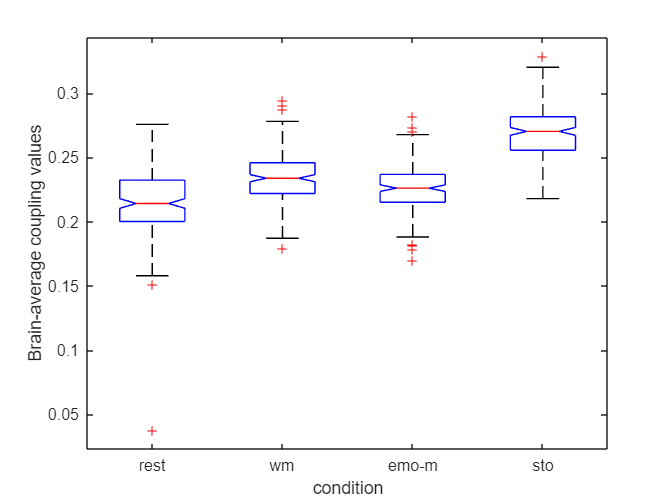

xlabel('condition')
ylabel('Brain-average coupling values')

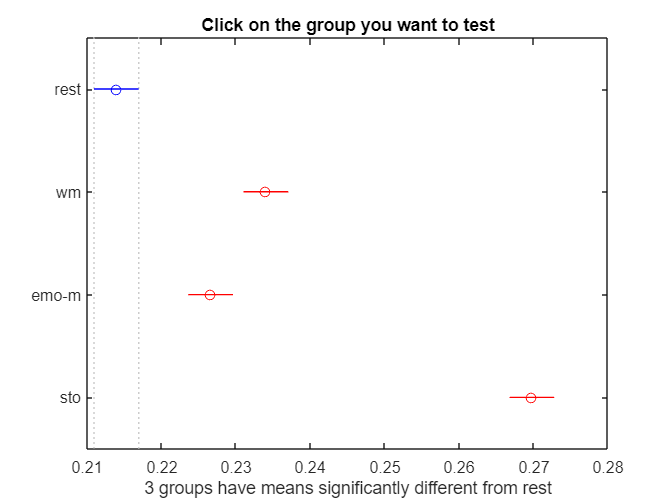

gnames = 4×1 cell array
    {'rest' }
    {'wm'   }
    {'emo-m'}
    {'sto'  }


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 6×6 table
    Group A    Group B    Lower Limit       A-B       Upper Limit     P-value  
    _______    _______    ___________    _________    ___________    __________

       1          2        -0.026098     -0.020094     -0.014089     1.9605e-17
       1          3        -0.018681     -0.012676    -0.0066715     3.4928e-07
       1          4         -0.06184     -0.055835     -0.049831              0
       2          3        0.0014129     0.0074175      0.013422      0.0082025
       2          4        -0.041746     -0.035742     -0.029737              0
       3          4        -0.049164     -0.043159     -0.037155              0
